**Chapter 3**

Converting TF to SS in different forms

'Numerator-denominator representation conversion'

ans = 'Numerator-denominator representation conversion'

% Display label.
'Controller canonical form' % Display label.

ans = 'Controller canonical form'

num=24; % Define numerator of
% G(s)=C(s)/R(s).
den=[1 9 26 24]; % Define denominator of G(s).
[A,B,C,D]=tf2ss(num,den) % Convert G(s) to controller

A =     -9   -26   -24
     1     0     0
     0     1     0


B =      1
     0
     0


C =      0     0    24


D = 0

% canonical form, store matrices
% A, B, C, D, and display.
'Phase-variable form' % Display label.

ans = 'Phase-variable form'

P=[0 0 1;0 1 0;1 0 0]; % Form transformation matrix.
Ap=inv(P)*A*P % Form A matrix, phase-variable

Ap =      0     1     0
     0     0     1
   -24   -26    -9


% form.
Bp=inv(P)*B % Form B vector, phase-variable

Bp =      0
     0
     1


% form.
Cp=C*P % Form C vector, phase-variable

Cp =     24     0     0


% form.
Dp=D % Form D phase-variable form.

Dp = 0

'LTI object representation' % Display label.

ans = 'LTI object representation'

T=tf(num,den) % Represent T(s)=24/(s^3+9s^2 +

T =
 
            24
  -----------------------
  s^3 + 9 s^2 + 26 s + 24
 
Continuous-time transfer function.



% 26s+24) as an LTI transfer-
% function object.
Tss=ss(T) % Convert T(s) to state space.

Tss =
 
  A = 
         x1    x2    x3
   x1    -9  -6.5    -3
   x2     4     0     0
   x3     0     2     0
 
  B = 
       u1
   x1   2
   x2   0
   x3   0
 
  C = 
        x1   x2   x3
   y1    0    0  1.5
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



State Space to TF

'Non LTI' % Display label.

ans = 'Non LTI'

A=[0 1 0;0 0 1;-9 -8 -7]; % Represent A.
B=[7;8;9]; % Represent B.
C=[2 3 4]; % Represent C.
D=0; % Represent D.
'Ttf(s)' % Display label.

ans = 'Ttf(s)'

[num,den]=ss2tf(A,B,C,D,1) % Convert state-space

num =          0   74.0000 -199.0000 -235.0000


den =     1.0000    7.0000    8.0000    9.0000


% representation to a
% transfer function represented as
% a numerator and denominator in
% polynomial form, G(s)=num/den,
% and display num and den.
'LTI' % Display label.

ans = 'LTI'

Tss=ss(A,B,C,D) % Form LTI state-space model.

Tss =
 
  A = 
       x1  x2  x3
   x1   0   1   0
   x2   0   0   1
   x3  -9  -8  -7
 
  B = 
       u1
   x1   7
   x2   8
   x3   9
 
  C = 
       x1  x2  x3
   y1   2   3   4
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



'Polynomial form, Ttf(s)' % Display label.

ans = 'Polynomial form, Ttf(s)'

Ttf=tf(Tss) % Transform from state space to

Ttf =
 
  74 s^2 - 199 s - 235
  ---------------------
  s^3 + 7 s^2 + 8 s + 9
 
Continuous-time transfer function.



% transfer function in polynomial
% form.
'Factored form, Tzpk(s)' % Display label.

ans = 'Factored form, Tzpk(s)'

Tzpk=zpk(Tss) % Transform from state space to

Tzpk =
 
      74 (s+0.8878) (s-3.577)
  --------------------------------
  (s+5.903) (s^2 + 1.097s + 1.525)
 
Continuous-time zero/pole/gain model.



% transfer function in factored
% form.

**Chapter 4**

We can use MATLAB to calculate characteristics of a second‐order system, such as damping ratio, ζ; natural frequency, ωn; percent overshoot, %OS (pos); settling time, Ts ; and peak time, Tp .

p1=[1 3+7*i]; % Define polynomial containing
% first pole.
p2=[1 3-7*i]; % Define polynomial containing
% second pole.
deng=conv(p1,p2); % Multiply the two polynomials to
% find the 2nd order polynomial,
% as^2+bs+c.
omegan=sqrt(deng(3)/deng(1)) % Calculate the natural frequency,

omegan = 7.6158

% sqrt(c/a).
zeta=(deng(2)/deng(1))/(2*omegan)

zeta = 0.3939

% Calculate damping ratio,
% ((b/a)/2*wn).
Ts=4/(zeta*omegan) % Calculate settling time,

Ts = 1.3333

% (4/z*wn).
Tp=pi/(omegan*sqrt(1 -zeta^2)) % Calculate peak time,

Tp = 0.4488

% pi/wn*sqrt(1 -z^2).
pos=100*exp(-zeta*pi/sqrt(1 -zeta^2))

pos = 26.0176

% Calculate percent overshoot
% (100*e^(-z*pi/sqrt(1-z^2)).

System step responses. These responses are particularly valuable when the system is not a pure two‐pole system and has additional poles or zeros. We can obtain a plot of the step response of a transfer function, T(s) =num/den, using the command step(T), where T is an LTI transfer‐function object. Multiple plots also can be obtained using step(T1,T2,...). Information about the plots obtained with step(T) can be found by left‐clicking the mouse on the curve. You can find the curve's label as well as the coordinates of the point on which you clicked. Right‐clicking away from a curve brings up a menu. From this menu you can select (1) system responses to be displayed and (2) response characteristics to be displayed, such as peak response. When selected, a dot appears on the curve at the appropriate point. Let your mouse rest on the point to read the value of the characteristic. You may also select (3) choice for grid on or off, (4) choice to normalize the curve, and (5) properties, such as labels, limits, units, style, and characteristics. If we add the left‐hand side,[y,t]=step(T), we create vectors containing the plot's points, where y is the output vector and t is the time vector. For this case, a plot is not made until the plot(t,y) command is given, where we assume we want to plot the output (y) versus time (t). We can label the plot, the x‐axis, and the y‐axis with title('ab'), xlabel('ab'), and ylabel('ab'), respectively. The command clf clears the graph prior to plotting. Finally, text can be placed anywhere on the graph using the command text(X,Y,'text'), where (X,Y) are the graph coordinates where 'text' will be displayed

'Test Run' % Display label.

ans = 'Test Run'

clf % Clear graph.
numt1=[24.542]; % Define numerator of T1.
dent1=[1 4 24.542]; % Define denominator of T1.
'T1(s)' % Display label.

ans = 'T1(s)'

T1=tf(numt1,dent1) % Create and display T1(s).

T1 =
 
        24.54
  -----------------
  s^2 + 4 s + 24.54
 
Continuous-time transfer function.



step(T1) % Run a demonstration step response
% plot
title ('Test Run of T1(s)') % Add title to graph.


'Complete Run' % Display label.

ans = 'Complete Run'

[y1,t1]=step(T1); % Run step response of T1 and
% collect points.
numt2=[245.42]; % Define numerator of T2.
p1=[1 10]; % Define (s+10) in denominator
% of T2.
p2=[1 4 24.542]; % Define (s^2+4s+24.542) in
% denominator of T2.
dent2=conv(p1,p2); % Multiply (s + 10)(s^2+4s+24.542)
% for denominator of T2.
'T2(s)' % Display label.

ans = 'T2(s)'

T2=tf(numt2,dent2) % Create and display T2.

T2 =
 
              245.4
  ------------------------------
  s^3 + 14 s^2 + 64.54 s + 245.4
 
Continuous-time transfer function.



[y2,t2]=step(T2); % Run step response of T2 and
% collect points.
numt3=[73.626]; % Define numerator of T3.
p3=[1 3]; % Define (s+3) in denominator
% of T3.
dent3=conv(p3,p2); % Multiply (s+3)(s^2+4s+24.542)
% for denominator of T3.
'T3(s)' % Display label.

ans = 'T3(s)'

T3=tf(numt3,dent3) % Create and display T3.

T3 =
 
              73.63
  -----------------------------
  s^3 + 7 s^2 + 36.54 s + 73.63
 
Continuous-time transfer function.



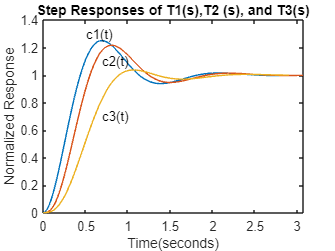

[y3,t3]=step(T3); % Run step response of T3 and
% collect points.
clf % Clear graph.
plot(t1,y1,t2,y2,t3,y3) % Plot acquired points with all
% three plots on one graph.
title ('Step Responses of T1(s),T2 (s), and T3(s)')
% Add title to graph.
xlabel('Time(seconds)') % Add time axis label.
ylabel ('Normalized Response') % Add response axis label.
text(0.7,0.7,'c3(t)') % Label step response of T1.
text(0.7,1.1,'c2(t)') % Label step response of T2.
text(0.5,1.3,'c1(t)') % Label step response of T3.

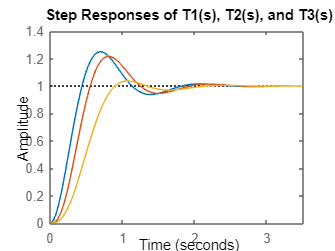

step(T1,T2,T3) % Use alternate method of plotting
% step responses.
title ('Step Responses of T1(s), T2(s), and T3(s)')

% Add title to graph.

As a final example, let us use MATLAB to do the UFSS Case Study in the text (Johnson, 1980). We introduce table lookup to find the rise time. Using the interp1(y,t,y1) command, we set up a table of values of amplitude, y, and time, t, from the step response and look for the value of time for which the amplitude is y1=0.1 and 0.9. We also generate time response data over a defined range of time using t=a:b:c followed by [y,t]=step(G,t). Here G is an LTI transfer‐function object and t is the range for the time axis, where a is the initial time, b is the time step size, and c is the final time; y is the output.

clf % Clear graph.
'(a)' % Display label.

ans = '(a)'

numg=0.0169; % Define numerator of 2nd order
% approximation of G(s).
deng=[1 0.226 0.0169]; % Define 2nd order term of
% denominator of G(s).
'G(s)' % Display label.

ans = 'G(s)'

G=tf(numg,deng) % Create and display G(s).

G =
 
          0.0169
  ----------------------
  s^2 + 0.226 s + 0.0169
 
Continuous-time transfer function.



omegan=sqrt(deng(3)) % Find natural frequency.

omegan = 0.1300

zeta=deng(2)/(2*omegan) % Find damping ratio.

zeta = 0.8692

Ts=4/(zeta*omegan) % Find settling time.

Ts = 35.3982

Tp=pi/(omegan*sqrt(1-zeta^2)) % Find peak time.

Tp = 48.8790

pos=exp(-zeta*pi/sqrt(1-zeta^2))*100

pos = 0.3993

% Find percent overshoot.
t=0:0.1:35; % Limit time to find rise time. t=0
% to 35 in steps of 0.1.
[y,t]=step(G,t); % Generate and save points of step
% response over defined range of t.
Tlow=interp1(y,t,0.1); % Search table for time when
% y=0.1*finalvalue.
Thi=interp1(y,t,0.9); % Search table for
% time=0.9*finalvalue.
Tr=Thi-Tlow % Calculate rise time.

Tr = 21.1359

'(b)' % Display label.

ans = '(b)'

numc=0.125*[1 0.435]; % Define numerator of C(s).
denc=conv(poly([0 -1.23]),[1 0.226 0.0169]);
% Define denominator of C(s).
[K,p,k]=residue(numc,denc) % Find partial-fraction expansion.

K =    0.0645 + 0.0000i
  -1.3402 + 1.7387i
  -1.3402 - 1.7387i
   2.6158 + 0.0000i


p =   -1.2300 + 0.0000i
  -0.1130 + 0.0643i
  -0.1130 - 0.0643i
   0.0000 + 0.0000i



k =

     []



'(d)' % Display label.

ans = '(d)'

numg=0.125*[1 0.435]; % Define numerator of G(s).
deng=conv([1 1.23],[1 0.226 0.0169]);
% Define denominator of G(s).
'G(s)' % Display label.

ans = 'G(s)'

G=tf(numg,deng) % Create and display G(s).

G =
 
           0.125 s + 0.05437
  ------------------------------------
  s^3 + 1.456 s^2 + 0.2949 s + 0.02079
 
Continuous-time transfer function.



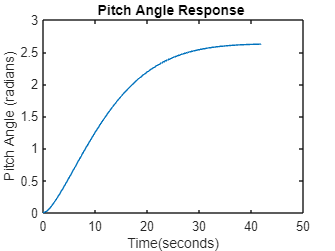

[y,t]=step(G); % Generate complete step response
% and collect points.
plot(t,y) % Plot points.
title ('Pitch Angle Response ') % Add title.
xlabel('Time(seconds)') % label time axis.
ylabel ('Pitch Angle (radians)') % Label y-axis.

**Chapter 5**

Let us demonstrate the three methods for finding the total transfer function by looking at the back endpapers and finding the closed‐loop transfer function of the pitch control loop for the UFSS with K1 = K2 = 1 (Johnson, 1980). The last method using append and connect requires that all subsystems be proper (the order of the numerator cannot be greater than the order of the denominator). The pitch rate sensor violates this requirement. Thus, for the third method, we perform some block diagram maneuvers by pushing the pitch rate sensor to the left past the summing junction and combining the resulting blocks with the pitch gain and the elevator actuator. These changes are reflected in the program. You should verify all computer results with hand calculations.

'Solution via Series, Parallel, & Feedback Commands'

ans = 'Solution via Series, Parallel, & Feedback Commands'

% Display labels.
numg1=[-1]; % Define numerator of G1(s).
deng1=[1]; % Define denominator of G1(s).
numg2=[0 2]; % Define numerator of G2(s).
deng2=[1 2]; % Define denominator of G2 (s).
numg3=-0.125*[1 0.435]; % Define numerator of G3(s).
deng3=conv([1 1.23],[1 0.226 0.0169]);
% Define denominator of G3(s).
numh1=[-1 0]; % Define numerator of H1(s).
denh1=[0 1]; % Define denominator of H1(s).
G1=tf(numg1,deng1); % Create LTI transfer function,
% G1(s).
G2=tf(numg2,deng2); % Create LTI transfer function,
% G2(s).
G3=tf(numg3,deng3); % Create LTI transfer function,
% G3(s).
H1=tf (numh1,denh1); % Create LTI transfer function,
% H1(s).
G4=series(G2,G3); % Calculate product of elevator
% and vehicle dynamics.
G5=feedback(G4,H1); % Calculate closed-loop transfer
% function of inner loop.
Ge=series(G1,G5); % Multiply inner-loop transfer
% function and pitch gain.
'T(s) via Series, Parallel, & Feedback Commands'

ans = 'T(s) via Series, Parallel, & Feedback Commands'

% Display label.
T=feedback(Ge,1) % Find closed-loop transfer

T =
 
                  0.25 s + 0.1087
  -----------------------------------------------
  s^4 + 3.456 s^3 + 3.457 s^2 + 0.9693 s + 0.1503
 
Continuous-time transfer function.



% function.
'Solution via Algebraic Operations'

ans = 'Solution via Algebraic Operations'

% Display label.
clear % Clear session.
numg1=[-1]; % Define numerator of G1(s).
deng1=[1]; % Define denominator of G1(s).
numg2=[0 2]; % Define numerator of G2(s).
deng2=[1 2]; % Define denominator of G2(s).
numg3=-0.125*[1 0.435]; % Define numerator of G3(s).
deng3=conv([1 1.23],[1 0.226 0.0169]);
% Define denominator of G3(s).
numh1=[-1 0]; % Define numerator of H1(s).
denh1=[0 1]; % Define denominator of H1(s).
G1=tf (numg1,deng1); % Create LTI transfer function, G1(s).
G2=tf (numg2,deng2); % Create LTI transfer function, G2(s).
G3=tf (numg3,deng3); % Create LTI transfer function, G3(s).
H1=tf (numh1,denh1); % Create LTI transfer function, H1(s).
G4=G3*G2; % Calculate product of elevator and
% vehicle dynamics.
G5=G4/(1+G4*H1); % Calculate closed-loop transfer
% function of inner loop.
G5=minreal(G5); % Cancel common terms.
Ge=G5*G1; % Multiply inner-loop transfer
% functions.
'T(s) via Algebraic Operations' % Display label.

ans = 'T(s) via Algebraic Operations'

T=Ge/(1+Ge); % Find closed-loop transfer function.
T=minreal(T) % Cancel common terms.

T =
 
                  0.25 s + 0.1088
  -----------------------------------------------
  s^4 + 3.456 s^3 + 3.457 s^2 + 0.9693 s + 0.1503
 
Continuous-time transfer function.



' Solution via Append & Connect Commands'

ans = ' Solution via Append & Connect Commands'

% Display label.
'G1(s)=(-K1)*(1/(-K2s))=1/s' % Display label.

ans = 'G1(s)=(-K1)*(1/(-K2s))=1/s'

numg1=[1]; % Define numerator of G1(s).
deng1=[1 0]; % Define denominator of G1(s).
G1=tf(numg1,deng1) % Create LTI transfer function,

G1 =
 
  1
  -
  s
 
Continuous-time transfer function.



% G1(s)=pitch gain*
% 1 (1/Pitch rate sensor).
'G2(s)=(-K2s)*(2/(s+2)' % Display label.

ans = 'G2(s)=(-K2s)*(2/(s+2)'

numg2=[-2 0]; % Define numerator of G2(s).
deng2=[1 2]; % Define denominator of G2(s).
G2=tf(numg2,deng2) % Create LTI transfer function,

G2 =
 
  -2 s
  -----
  s + 2
 
Continuous-time transfer function.



% G2(s)=pitch rate sensor*vehicle
% dynamics.
'G3(s)=-0.125(s +0.435)/((s+1.23)(s^2+0.226s+0.0169))'

ans = 'G3(s)=-0.125(s +0.435)/((s+1.23)(s^2+0.226s+0.0169))'

% Display label.
numg3=-0.125*[1 0.435]; % Define numerator of G3(s).
deng3=conv([1 1.23],[1 0.226 0.0169]);
% Define denominator of G3(s).
G3=tf(numg3,deng3); % Create LTI transfer function,
% G3(s)=vehicle dynamics.
System=append(G1,G2,G3) % Gather all subsystems.

System =
 
  From input 1 to output...
       1
   1:  -
       s
 
   2:  0
 
   3:  0
 
  From input 2 to output...
   1:  0
 
       -2 s
   2:  -----
       s + 2
 
   3:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
                -0.125 s - 0.05437
   3:  ------------------------------------
       s^3 + 1.456 s^2 + 0.2949 s + 0.02079
 
Continuous-time transfer function.



input=1; % Input is at first subsystem,
% G1(s).
output=3; % Output is output of third
% subsystem, G3(s).
Q=[1 -3 0 % Subsystem 1, G1(s), gets its
% input from the negative of the
% output of subsystem 3, G3(s).
2 1 -3 % Subsystem 2, G2(s), gets its
% input from subsystem 1, G1(s),
% and the negative of the output
% of subsystem 3, G3(s).
3 2 0]; % Subsystem 3, G3(s), gets its
% input from subsystem 2, G2(s).
T=connect(System,Q,input,output);
% Connect the subsystems.
'T(s) via Append & Connect Commands'

ans = 'T(s) via Append & Connect Commands'

% Display label.
T=tf(T); % Create LTI closed-loop transfer
% function.
T=minreal(T) % Cancel common terms.

T =
 
                  0.25 s + 0.1087
  -----------------------------------------------
  s^4 + 3.456 s^3 + 3.457 s^2 + 0.9693 s + 0.1503
 
Continuous-time transfer function.



We can use MATLAB to calculate the closed‐loop characteristics of a second‐order system, such as damping ratio, ζ; natural frequency, ωn; percent overshoot, %OS (pos); settling time, Ts ; and peak time, Tp . The command [numt,dent]=tfdata(T,'v') extracts the numerator and denominator of T(s) for a single‐input/single‐output system from which the calculations are based. The argument 'v' returns the numerator and denominator as simple row vectors. Omitting 'v' would return the numerator and denominator as cell arrays requiring more steps to obtain the row vectors. We end by generating a plot of the closed‐loop step response. Let us look at Example 5.3 in the text. 

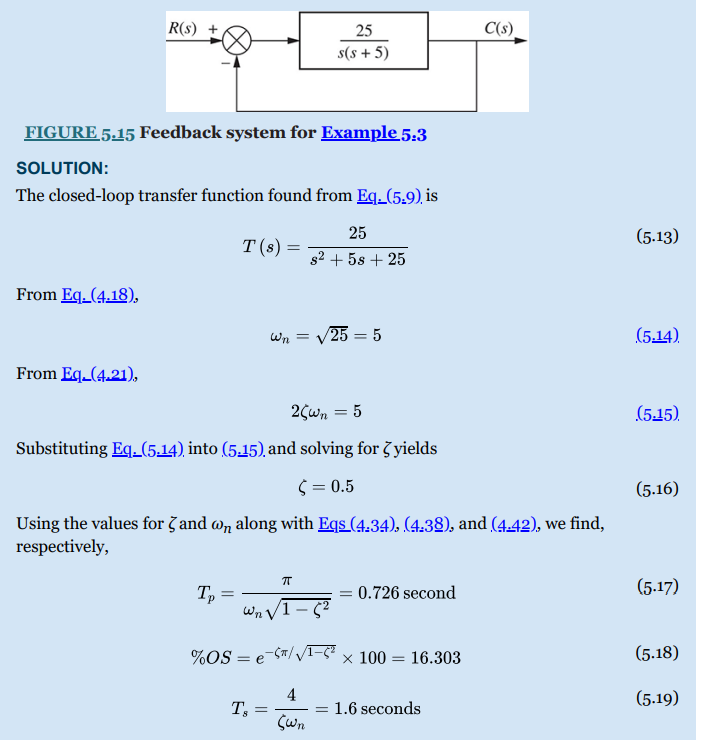

numg=[25]; % Define numerator of G(s).
deng=poly([0 -5]); % Define denominator of G(s).
'G(s)' % Display label.

ans = 'G(s)'

G=tf(numg,deng) % Create and display G(s).

G =
 
     25
  ---------
  s^2 + 5 s
 
Continuous-time transfer function.



'T(s)' % Display label.

ans = 'T(s)'

T=feedback(G,1) % Find T(s).

T =
 
        25
  --------------
  s^2 + 5 s + 25
 
Continuous-time transfer function.



[numt,dent]=tfdata(T,'v'); % Extract numerator & denominator
% of T(s).
wn=sqrt(dent(3)) % Find natural frequency.

wn = 5

z=dent(2)/(2*wn) % Find damping ratio.

z = 0.5000

Ts=4/(z*wn) % Find settling time.

Ts = 1.6000

Tp=pi/(wn*sqrt(1-z^2)) % Find peak time.

Tp = 0.7255

pos=exp(-z*pi/sqrt(1-z^2))*100 % Find percent overshoot.

pos = 16.3034

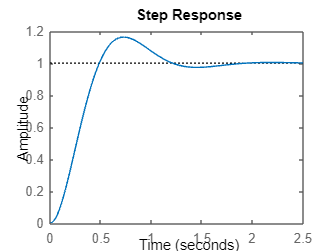

step(T) % Generate step response.

MATLAB can be used to convert transfer functions to state space in a specified form. The command [Acc Bcc Ccc Dcc]=tf2ss(num,den) can be used to convert T(s)=num/den into controller canonical form with matrices and vectors Acc, Bcc, Ccc, and Dcc. We can then form an LTI state‐space object using Scc=ss (Acc,Bcc,Ccc,Dcc). This object can then be converted into parallel form using Sp=canon(Scc,'type'), where type=modal yields the parallel form. Another choice, not used here, is type=companion, which yields a right companion system matrix. Transformation matrices can be used to convert to other representations. As an example, let us convert C (s) /R (s) = 24/ [(s + 2)(s + 3)(s + 4)] into a parallel representation in state space, as is done in Section 5.7—Parallel Form. Notice that the product of values in the B and C vectors yields the same product as the results in Eqs. (5.49) and (5.50). Thus, the two solutions are the same, but the state variables are ordered differently, and the gains are split between the B and C vectors. We can also extract the system matrices from the LTI object using [A,B,C,D]=ssdata(S), where S is a state‐space LTI object and A, B, C, D, are its associated matrices and vectors. 


numt=24; % Define numerator of T(s).
dent=poly([-2 -3 -4]); % Define denominator of T(s).
'T(s)' % Display label.

ans = 'T(s)'

T=tf(numt,dent) % Create and display T(s).

T =
 
            24
  -----------------------
  s^3 + 9 s^2 + 26 s + 24
 
Continuous-time transfer function.



[Acc Bcc Ccc Dcc]=tf2ss(numt,dent);
% Convert T(s) to controller
% canonical form.
Scc=ss(Acc,Bcc,Ccc,Dcc); % Create LTI controller canonical
% state-space object.
Sp=canon(Scc,'modal'); % Convert controller canonical form
% to parallel form.
'Controller Canonical Form' % Display label.

ans = 'Controller Canonical Form'

[Acc,Bcc,Ccc,Dcc]=ssdata(Scc) % Extract and display controller

Acc =     -9   -26   -24
     1     0     0
     0     1     0


Bcc =      1
     0
     0


Ccc =      0     0    24


Dcc = 0

% canonical form matrices.
'Parallel Form' % Display label.

ans = 'Parallel Form'

[Ap,Bp,Cp,Dp]=ssdata(Sp) % Extract and display parallel form

Ap =    -4.0000         0         0
         0   -3.0000         0
         0         0   -2.0000


Bp =    24.0000
   34.0000
   12.0000


Cp =     0.5000   -0.7059    1.0000


Dp = 0

% matrices.

Other forms

Pinv=[2 0 0; 3 2 0; 1 4 5]; % Define P inverse.
P=inv(Pinv) % Calculate P.

P =     0.5000         0         0
   -0.7500    0.5000         0
    0.5000   -0.4000    0.2000


'Original' % Display label.

ans = 'Original'

Ax=[0 1 0;0 0 1;-2 -5 -7] % Define original A.

Ax =      0     1     0
     0     0     1
    -2    -5    -7


Bx=[0 0 1] % Define original B.

Bx =      0     0     1


Cx=[1 0 0] % Define original C.

Cx =      1     0     0


'Transformed' % Display label.

ans = 'Transformed'

Az=Pinv.*Ax.*P % Calculate new A.

Az =      0     0     0
     0     0     0
    -1     8    -7


Bz=Pinv.*Bx % Calculate new B.

Bz =      0     0     0
     0     0     0
     0     0     5


Cz=Cx.*P % Calculate new C.

Cz =     0.5000         0         0
   -0.7500         0         0
    0.5000         0         0


Using MATLAB's [P,d]=eig(A) command, where the columns of P are the eigenvectors of A and the diagonal elements of d are the eigenvalues of A, we can find the eigenvectors of the system matrix and then proceed to diagonalize the system. We can also use canon (S,'modal')to diagonalize an LTI object, S, represented in state space. 

A=[3 1 5;4 -2 7;2 3 1]; % Define original A.
B=[1;2;3]; % Define original B.
C=[2 4 6]; % Define original C.
[P,d]=eig(A) % Generate transformation matrix,

P =    -0.6403   -0.8098   -0.1951
   -0.6081    0.2726   -0.8522
   -0.4694    0.5195    0.4854


d =     7.6150         0         0
         0   -0.5438         0
         0         0   -5.0712


% P, and eigenvalues, d.
'Via Transformation' % Display label.

ans = 'Via Transformation'

Adt=inv(P)*A*P % Calculate diagonal system A.

Adt =     7.6150    0.0000         0
    0.0000   -0.5438   -0.0000
    0.0000         0   -5.0712


Bdt=inv(P)*B % Calculate diagonal system B.

Bdt =    -3.7884
    1.5547
    0.8535


Cdt=C*P % Calculate diagonal system C.

Cdt =    -6.5290    2.5874   -0.8868


'Via Canon Command' % Display label.

ans = 'Via Canon Command'

S=ss(A,B,C,0) % Create state‐space LTI object

S =
 
  A = 
       x1  x2  x3
   x1   3   1   5
   x2   4  -2   7
   x3   2   3   1
 
  B = 
       u1
   x1   1
   x2   2
   x3   3
 
  C = 
       x1  x2  x3
   y1   2   4   6
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% for original system.
Sp=canon(S,'modal') % Calculate diagonal system via

Sp =
 
  A = 
            x1       x2       x3
   x1    7.615        0        0
   x2        0  -0.5438        0
   x3        0        0   -5.071
 
  B = 
           u1
   x1  -3.788
   x2   1.555
   x3  0.8535
 
  C = 
            x1       x2       x3
   y1   -6.529    2.587  -0.8868
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



% canon command.

**Chapter 6**

MATLAB can solve for the poles of a transfer function in order to determine stability. To solve for the poles of T(s) use the pole(T) command. Let us look at Example 6.7 in the text.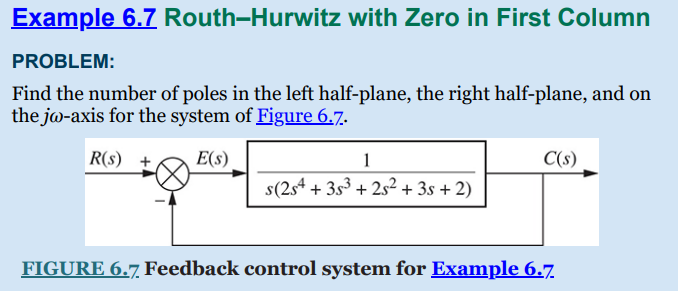

numg=1; % Define numerator of G(s).
deng=conv ([1 0],[2 3 2 3 2]); % Define denominator of G(s).
G=tf(numg,deng); % Create G(s) object.
'T(s)' % Display label.

ans = 'T(s)'

T=feedback(G,1) % Calculate closed-loop T(s)

T =
 
                     1
  ---------------------------------------
  2 s^5 + 3 s^4 + 2 s^3 + 3 s^2 + 2 s + 1
 
Continuous-time transfer function.



% object.
% Negative feedback is default
% when there is no sign parameter.
poles=pole(T) % Find poles of T(s).

poles =   -1.3307 + 0.0000i
   0.3284 + 0.8899i
   0.3284 - 0.8899i
  -0.4131 + 0.4969i
  -0.4131 - 0.4969i


We can use MATLAB to find the range of gain for stability by generating a loop, changing gain, and finding at what gain we obtain right–half‐plane poles. Example 6.9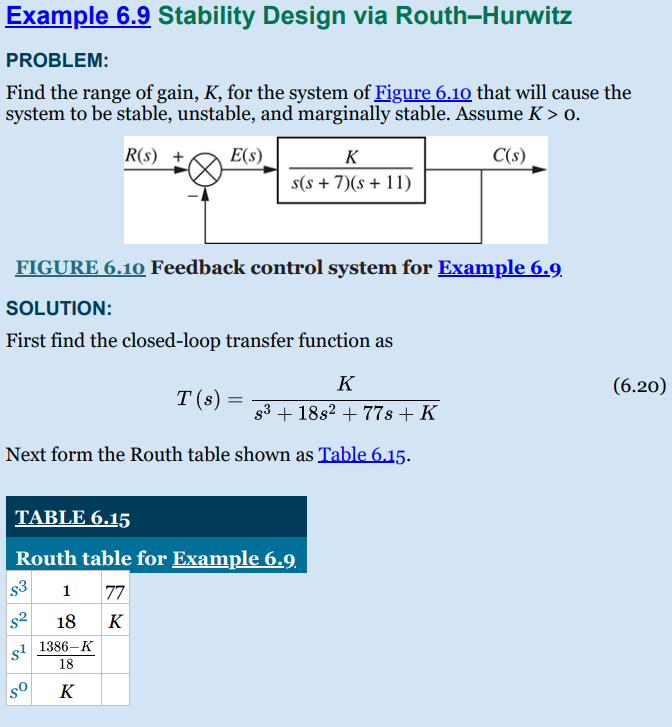

K=[1:1:2000]; % Define range of K from 1 to 2000
% in steps of 1.
for n=1:length(K); % Set up length of DO LOOP to equal
% number of K values to be tested.
dent=[1 18 77 K(n)]; % Define the denominator of T(s)
% for the nth value of K.
poles=roots(dent); % Find the poles for the nth value
% of K.
r=real(poles); % Form a vector containing the real
% parts of the poles for K(n).
if max(r) >=0, % Test poles found for the nth
% value of K for a real value ≥ 0.
poles % Display first pole values where
% there is a real part ≥ 0.
K=K(n) % Display corresponding value of K.
break % Stop loop if rhp poles are found.
end % End if.
end % End for.

poles =  -18.0025 + 0.0000i
   0.0012 + 8.7775i
   0.0012 - 8.7775i


K = 1387

Or using routh table script: (u have to add it to ur matlab path it'll give u an error and u just click the add folder to path option)

(you use the denominator of the closed loop transfer function)

syms s K
RouthHurwitzSym(s^3+18*s^2+77*s+K)

$$ans = \left(\begin{array}{cc} 1 & 77\\ 18 & K+1\\ \frac{1385}{18}-\frac{K}{18} & 0\\ K+1 & 0 \end{array}\right)$$

%using second last row; double check the values r sometimes off by 1
eqn = (1386-K)/18;
solve(eqn)

$$ans = 1386$$

%stable for K>1386

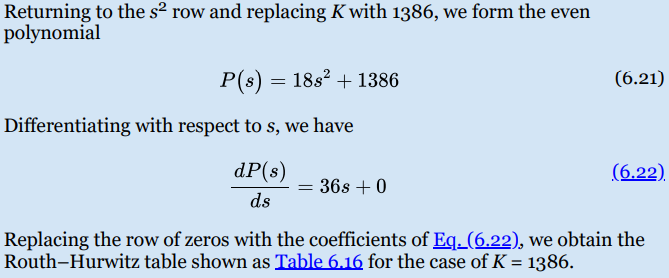

Ps = 18*s^2+1386;
dPs = diff(Ps)

$$dPs = 36\,s$$

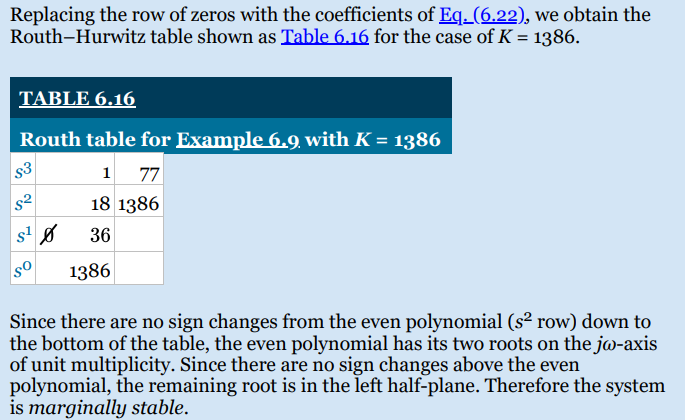

We can use MATLAB to determine the stability of a system represented in state space by using the command eig(A) to find the eigenvalues of the system matrix, A. Let us apply the concept to Example 6.11 in the text.

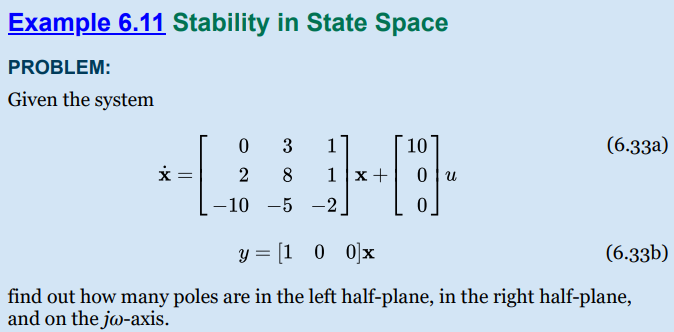

'(ch6apB3) Example 6.11' % Display label.

ans = '(ch6apB3) Example 6.11'

A=[0 3 1;2 8 1;-10 -5 -2] % Define system matrix, A.

A =      0     3     1
     2     8     1
   -10    -5    -2


eigenvalues=eig(A) % Find eigenvalues.

eigenvalues =   -0.8821 + 2.4330i
  -0.8821 - 2.4330i
   7.7642 + 0.0000i


2018 Exam question

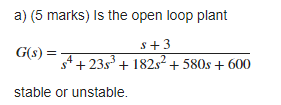

RouthHurwitzSym(s^4+23*s^3+182*s^2+580*s+600)

$$ans = \left(\begin{array}{ccc} 1 & 182 & 601\\ 23 & 580 & 0\\ \frac{3606}{23} & 601 & 0\\ \frac{2951}{6} & 0 & 0\\ 601 & 0 & 0 \end{array}\right)$$

**Chapter 7**